# МЕТОДЫ ОПТИМИЗАЦИИ

## Семинар 12. Решение задачи метода наименьших квадратов итерационными методами

### Градиент суммы квадратов и матрица Якоби

Задача метода наименьших квадратов, состоит в том, чтобы минимизировать квадрат модуля ошибки между результатами измерений и предсказанием модели:


$$\Phi(\vec{x})=\frac{1}{2} \vec{r}\cdot\vec{r}$$


Квадрат модуля - скалярное произведение вектора самого на себя, вектор ошибки  "живет" в пространстве с базисными векторами $\hat{e}_j$, размерность этого пространства равна количеству экспериментальных точек. Вектор $\vec{x}$ - это вектор параметров оптимизации, он "живет" в пространстве с базисными векторами $\hat{x}_i$. Размерность этого пространства равна количеству переменных оптимизации.

В соотвествии с формулой для градиента:


$$\overleftrightarrow {J}=\nabla\vec{r}=\sum_{i,j} \frac {\partial r_j}{\partial x_i}\hat{x}_i\hat{e}_j$$


Координаты этой диады -  матрица Якоби.

Таким образом, матрица Якоби - это матрица, в которой элемент, стоящий на ***i***-й строке*** j***-го столбца - это значение производной ***j***-й координаты вектора ошибки по ***i***-й переменной оптимизации:


$$J_{ij} = \frac {\partial r_j}{\partial x_i}$$


Из формулы для градиента легко видеть, что, если  скалярная функция  представима в виде скалярного произведение некоторых векторов $f=\vec{a}\cdot\vec{b}$, то:


$$\nabla f=(\nabla \vec{a})\cdot \vec{b} + \vec{a} \cdot (\nabla \vec{b})$$


В частности, градиент скалярного  вектора самого на себя будет:


$$\nabla(\vec{r}\cdot\vec{r})=2((\nabla\vec{r})\cdot\vec{r})$$


Тогда градиент квадратичной невязки:


$$\nabla\Phi(\vec{x})=(\nabla\vec{r})\cdot \vec{r}$$


Эта формула  позволяет упростить задачу расчета градиента в тех случаях, когда мы можем посчитать матрицу Якоби аналитически.

На прошлом семинаре мы рассматривали универсальный градиентный оптимизатор, который на входе требовал функцию расчета невязки и функцию расчета градиента. Этот метод был применим для любой скалярной функции.

Сегодня мы делаем оптимизатор, который на входе требует функцию расчета вектора ошибки и функцию расчета матрицы Якоби. Этот оптимизатор применим для задачи наименьших квадратов, то есть, мы в явном виде предполагаем форму скалярной функции.

#### Градиентный оптимизатор с постоянным шагом

Теперь код для поиска минимума функции невязки градиентным методом может выглядеть так (ниже приведена упрощенная версия кода, полный код можно посмотреть в файле  grad_lsqr.m, который находится в папке с ливскриптом ):

#### Задача линейной регрессии

Рассмотрим на конкретном примере - задаче линейной регрессии. 

Вектор ошибки регрессии (раньше он обозначался $\vec{\epsilon}$):


$$\vec{r}=X\vec{b} - \vec{y}$$


Скалярная функция невязки для нее - это, соотвественно, квадрат модуля вектора ошибки.

Функция невязки в матричной записи:


$$\Phi(\vec{b})=\frac{1}{2}  \vec{r}^T\vec{r}=||X\vec{b}-\vec{y}||^2 = (X\vec{b}-\vec{y})^T( X\vec{b}-\vec{y}) $$


В диадной записи:


$$\Phi(\vec{b})=\frac{1}{2}  \vec{r}\cdot\vec{r}=|| \overleftrightarrow {X}\cdot \vec{b}-\vec{y}||^2 = (\overleftrightarrow {X} \cdot\vec{b}-\vec{y})\cdot( \overleftrightarrow {X}\cdot\vec{b}-\vec{y}) $$


Посчитаем градиент этой функции:


$$\nabla_b\Phi(\vec{b})=(\nabla_b\vec{r})\cdot\vec{r}$$


$X<=> \overleftrightarrow {X}=\sum_{ij}x_{ij}\hat{e}_i\hat{u}_j$  - матрица предикторов

$\vec{y}=\sum_i y_i\hat{e}_i, \vec{b}=\sum_k b_k\hat{u}_k$ - зависимая переменная

$\hat{e}_i$  - базисные вектора пространства столбцов  - то есть, это то пространство, в котором живут все вектора размером с вектор наших измеренных точек, в этом пространстве живут столбцы матрицы предикторов, вектор экспериментальных точек

 $\hat{u}_j$ - базисные вектора пространства строк  - то есть, это то пространство, в котором живут все вектора размером с вектор коэффициентов, в этом пространстве живет вектор $\vec{b}$


$$\vec{r}=\sum_{ij}x_{ij}\hat{e}_i\hat{u}_j\cdot\sum_k b_k\hat{u}_k-\sum_i y_i\hat{e}_i=\sum_{ij}x_{ij}b_j\hat{e}_i-\sum_i y_i\hat{e}_i$$


$\nabla_b=\sum_i \hat{u}_i\frac {\partial}{\partial_{bi}$ - оператор градиента по переменным оптимизации в пространстве переменных оптимизации


$$\nabla_b\vec{r}=\sum_k \hat{u}_k\frac {\partial}{\partial_{b_k}} [\sum_{ij}x_{ij}b_j\hat{e}_i-\sum_i y_i\hat{e}_i]=\sum_{ij}x_{ij} \hat{u}_j \hat{e}_i$$


Сравним  матрицу Якоби с выражением для матрицы предикторов линейной регрессии, видно, что: $J=X^T$

$\nabla_b\Phi(\vec{b})=\nabla_b\vec{r}\cdot \vec{r}= \overleftrightarrow {J} \cdot \vec{r}$                                                        (1)

В матричной форме это выражение имеет вид:


$$\nabla \Phi(\vec{b}) = X^T(X\vec{b}-\vec{y})$$


Если его приравнять к нулю (градиент равен нулю в точке экстремума), то мы получим нормальное уравнение для линейной регрессии: $X^TX\vec{b}=X^T\vec{y}$ 

Сейчас наша задача состоит в том, чтобы решить это уравнение итерационным методом, мы не будем приравнивать градиент к нулю, а будем искать решение итерационно. 

В данном случае матрица якоби  - постоянная, поэтому для расчета градиента функции невязки нам на каждой итерации надо только посчитать вектор ошибки.

По сравнению с предыдущим семинаром, где для расчета градиента мы исопльзовали простейшую форму численного дифференцирования, теперь мы сделаем новый градиентный оптимизатор, который будет использовать тот факт, что минимизируемая функция  - это сумма квадратов. 

Создание функций

 
clearvars
x_true =[-0.43; 0.58]; % вектор истинных значений параметров 
t_region = [-1,1];
noise = 0;
t = linspace(t_region(1),t_region(2),10)'; % вектор независимых переменных
y = x_true(1) + x_true(2)*t + noise*randn(size(t));% истинные значения параметров оптимизации x_true
%F = @(x)sum(((x(1) + x(2)*t) - y).^2); % воркпейс функции F содержит и экспериментальные и измеренные точки
X = [ones(numel(t),1), t]; % матрица предикторов

residual_function = @(b) (X*b - y)% функция расчета вектора невязки

residual_function = function_handle with value:
    @(b)(X*b-y)


Xt = transpose(X);
Jacobian = @(~)Xt; % функция расчета матрицы Якоби (якобиан в данном случае постоянный)

residual_function_workspace = functions(residual_function)

residual_function_workspace = struct with fields:
            function: '@(b)(X*b-y)'
                type: 'anonymous'
                file: 'C:\Users\user\AppData\Local\Temp\Editor_xzpqt\LiveEditorEvaluationHelperE1826587093.m'
           workspace: {[1×1 struct]}
    within_file_path: ''


% функция functions  возвращает метаданные указателя на функцию

disp("Матрица Якоби:")

Матрица Якоби:


Jacobian([0.1; 0.3])

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000


disp("Векор ошибки:")

Векор ошибки:


residual_function([0.1; 0.3])

ans =     0.8100
    0.7478
    0.6856
    0.6233
    0.5611
    0.4989
    0.4367
    0.3744
    0.3122
    0.2500


disp("Градиент в точке x_true:")

Градиент в точке x_true:


Jacobian(x_true)*residual_function(x_true)

ans =      0
     0


% запускаем оптимизатор
[xval,fval,iternumber,outflag]=grad_lsqr([0.0; 0.0],residual_function,Jacobian,"mu",1e-2,"N",100000)

xval =    -0.4265
    0.5800


fval = 5.9970e-05

iternumber = 100000

outflag = 1×3 logical array
   1   1   1


disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

Ошибка фиттинга:0.0034632


Видно, что ошибка определения истинных значений имеет тот же порядок, что и длина шага (**mu**), если мы не уперлись в ограничение на число итераций (**N**).

% сделаем еще прогон, чтобы посмотреть как алгоритм ставит точки
mu=0.05;
[xval,~,~,~,search_history]=grad_lsqr([0.0; 0.0],residual_function,Jacobian,"mu",mu,"N",100)

xval =    -0.4094
    0.5800


search_history =          0   -0.0438   -0.0869   -0.1293   -0.1705   -0.2106   -0.2491   -0.2857   -0.3198   -0.3507   -0.3777   -0.3997   -0.4159   -0.4259   -0.4301   -0.4300   -0.4302   -0.4294   -0.4330   -0.4207   -0.4587   -0.4095   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094   -0.4594   -0.4094
         0    0.0241    0.0494    0.0760    0.1042    0.1341    0.1660    0.2001    0.2367    0.2760    0.3181    0.3630    0.4103    0.4593    0.5091    0.5591    0.6091    0.5591    0.6090    0.5605    0.5931    0.5839    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800    0.5800  

% построим анимацию шагов работы алгоритма
ax = get_next_ax();

fig1


animated_Line = animatedline(ax,'Marker',"o",'LineStyle',"-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.01)
end
% построим контурное изображение функции невязки (чтобы убедиться что
% градиент перпендикулярен линиям постоянного уровня)
x_lim = ax.XLim;
y_lim = ax.YLim;

F_inter = @(x1,x2) residual_function([x1;x2])'*residual_function([x1;x2])/2

F_inter = function_handle with value:
    @(x1,x2)residual_function([x1;x2])'*residual_function([x1;x2])/2




hold(ax,"on");
    plot(x_true(1),x_true(2),"r*","MarkerSize",16);
    fcontour(ax,F_inter,[1.5*x_lim,1.5*y_lim],"LevelStep",0.2); % контурное изображение показывает линии постоянного значения 

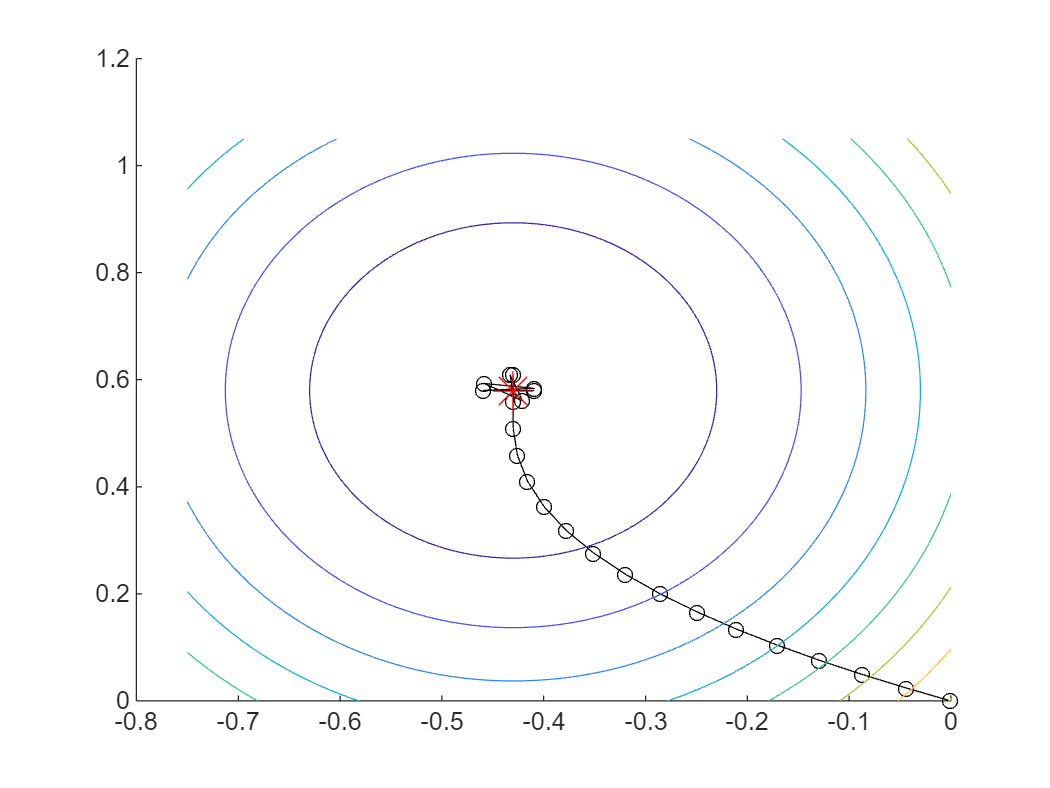

hold(ax,"off");

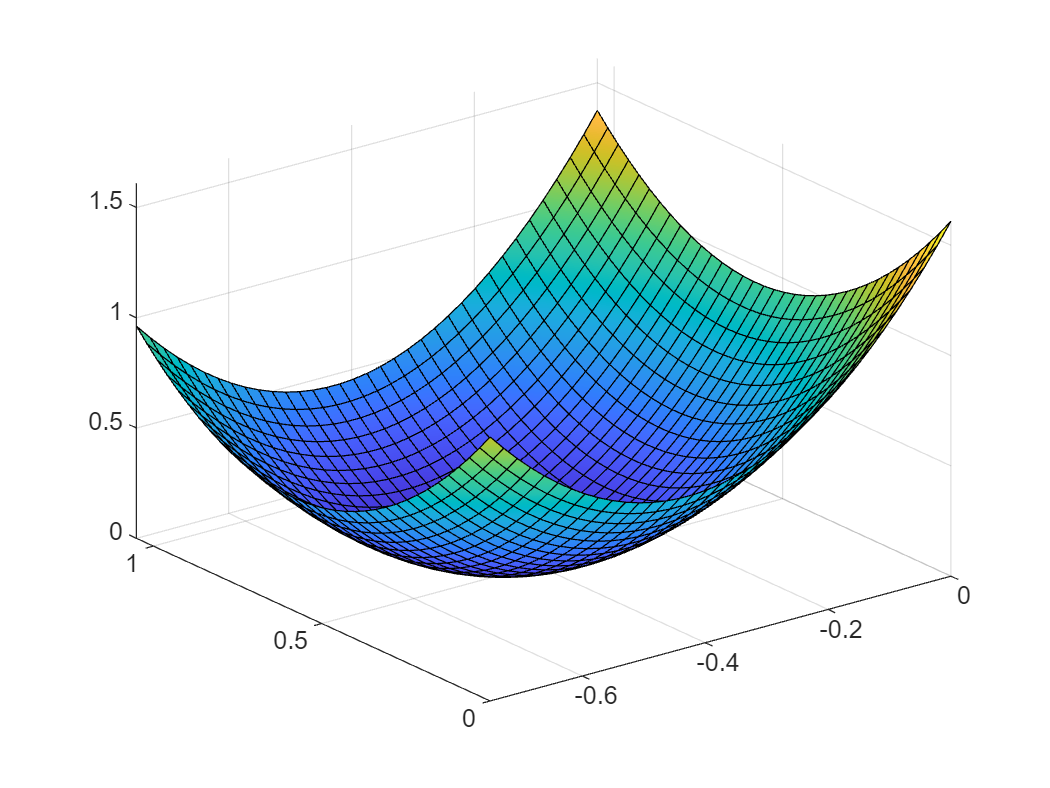

    fsurf(F_inter,[1.5*x_lim,1.5*y_lim])

#### Задача градиентного поиска с подбором длины шага

Теперь добавим линейный поиск длины шага. Для этого на каждой итерации будем решать отдельную подзадачу - поиск такой длины шага, которая давала бы минимальное значение функции невязки при фиксированном направлении 

[xval,fval,iternumber,outflag]=grad_lsqr_linesearch([0.0; 0.0],residual_function,Jacobian,"mu",0.1,"N",5000)

xval =    -0.4300
    0.5799


fval = 2.1120e-08

iternumber = 10

outflag = 1×3 logical array
   0   1   1


disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

Ошибка фиттинга:9.8464e-05


% сделаем еще прогон, чтобы посмотреть как алгоритм ставит точки
mu=0.071;
[xval,~,~,~,search_history]=grad_lsqr_linesearch([0.0; 0.0],residual_function,Jacobian,"mu",mu,"N",100)

xval =    -0.4300
    0.5799


search_history =          0   -0.4985   -0.3728   -0.4391   -0.4224   -0.4312   -0.4290   -0.4302   -0.4299   -0.4300
         0    0.2739    0.5028    0.5393    0.5697    0.5746    0.5786    0.5793    0.5798    0.5799


% построим анимацию шагов работы алгоритма
ax = get_next_ax();

fig4


animated_Line = animatedline(ax,'Marker',"o",'LineStyle',"-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.01)
end
% построим контурное изображение функции невязки (чтобы убедиться что
% градиент перпендикулярен линиям постоянного уровня)
x_lim = ax.XLim;
y_lim = ax.YLim;
Nx = 10;Ny = 10;
x_grid = linspace(x_lim(1),x_lim(2),Nx);
y_grid = linspace(y_lim(1),y_lim(2),Ny);
[X,Y] = meshgrid(x_grid,y_grid);

discrepancy_scalar_func = @(x1,x2) residual_function([x1;x2])'*residual_function([x1;x2])/2

discrepancy_scalar_func = function_handle with value:
    @(x1,x2)residual_function([x1;x2])'*residual_function([x1;x2])/2




hold(ax,"on");
    plot(x_true(1),x_true(2),"r*","MarkerSize",16);
    fcontour(ax,discrepancy_scalar_func,[1.5*x_lim,1.5*y_lim],"LevelStep",5); % контурное изображение показывает линии постоянного значения 

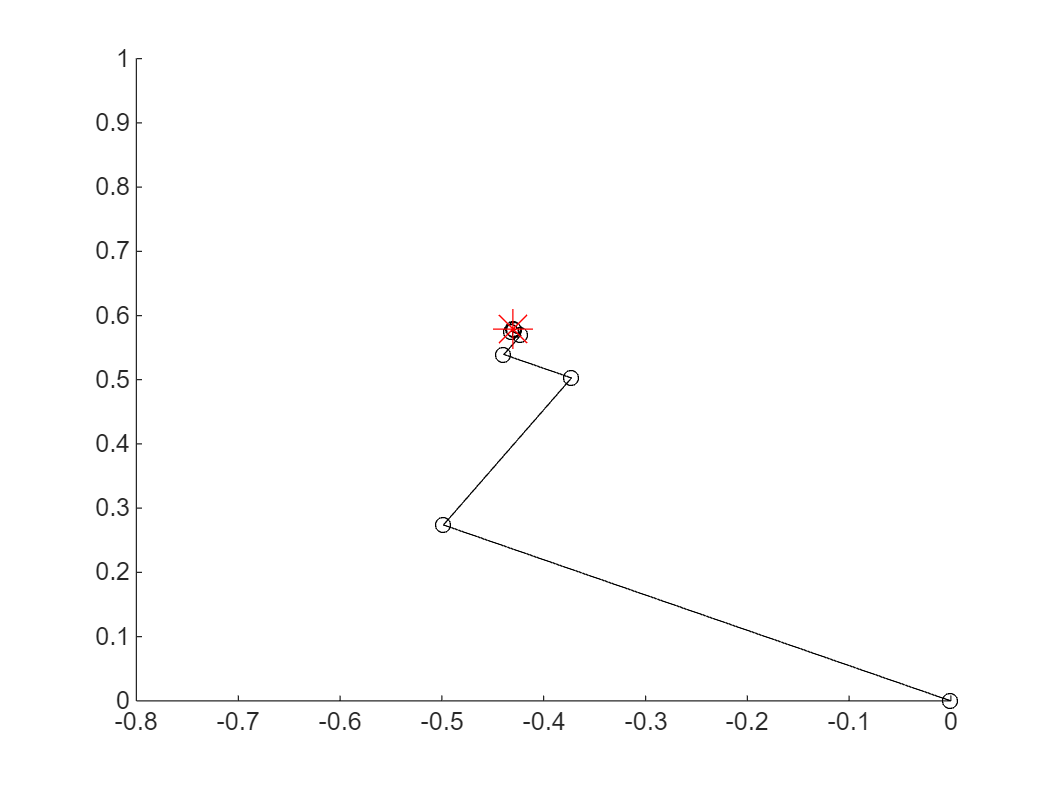

hold(ax,"off");

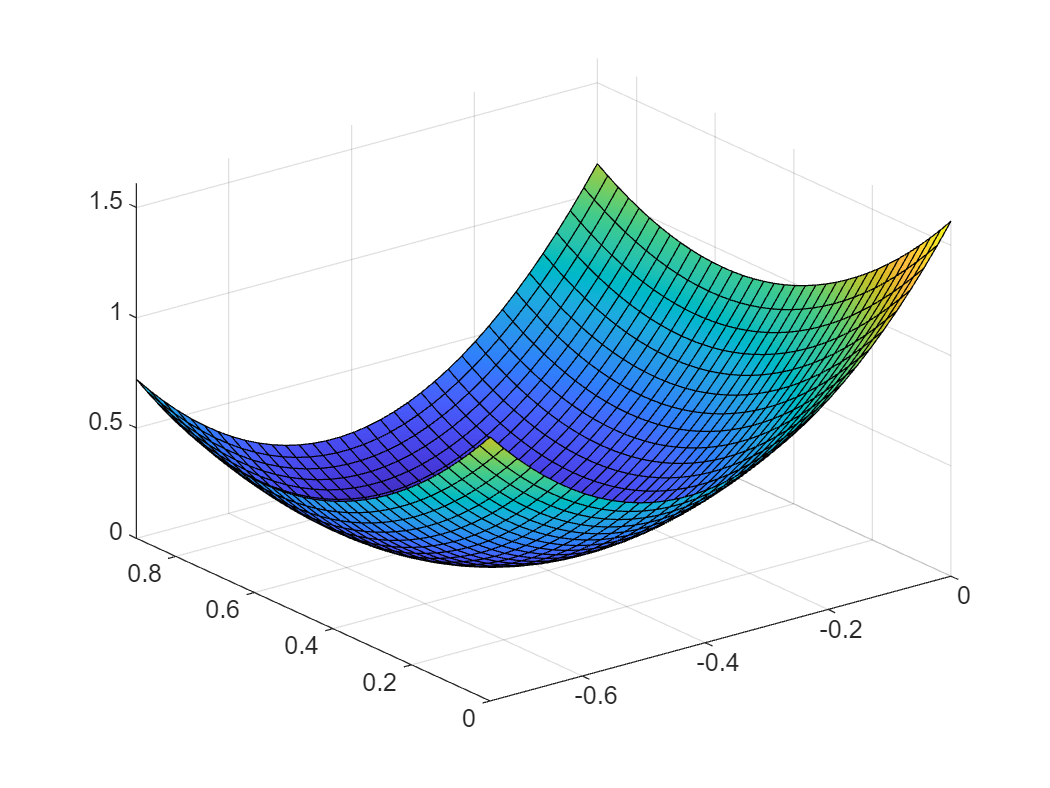

    fsurf(discrepancy_scalar_func,[1.5*x_lim,1.5*y_lim])

Теперь сравним скорость работы итерационного алгоритма и решения при помощи **mldivide**

    tic
    xval=grad_lsqr([0.0; 0.0],residual_function,Jacobian,"mu",0.01,"N",1000)

xval =    -0.4265
    0.5800


toc

Elapsed time is 0.006277 seconds.


tic;
    xval=grad_lsqr_linesearch([0.0; 0.0],residual_function,Jacobian,"mu",0.01,"N",1000)

xval =    -0.4300
    0.5799


toc

Elapsed time is 0.004981 seconds.


tic
    xval = [ones(length(t),1),t]\y % решение задачи классическим способом

xval =    -0.4300
    0.5800


toc

Elapsed time is 0.003166 seconds.


function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end